clear; clc;

% Define simulation parameters
T = 5;
dt = 0.01;
t_p = 0:dt:T;

% Define vehicle properties
m = 1.0;
g = 9.81;
r = 0.1;
I = 0.1;
u1 = 5.0;
u2 = 5.01;

% Define initial state
x0 = [0; 0; 0; 0; 0; 0]; 

%% Define the System Dynamics f(t, x)
f = @(x_sym) [
    x_sym(2);
    -(u1 + u2) * sin(x_sym(5)) / m;
    x_sym(4);
    (u1 + u2) * cos(x_sym(5)) / m - g;
    x_sym(6);
    r * (u1 - u2) / I
];

% Picard Iteration
max_iterations = 5;
x_picard = cell(1, max_iterations);   % stores solution after each k iterations

x_p = repmat(x0, 1, numel(t_p));      % initial guess: x(t) = x0 for all t


% Solve dynamics using ODE45 (Runge Kutta)

[t_rk,x_rk] = ode45(@(t,x) f(x), [0 T], x0');

x_rk = x_rk';
t_rk = t_rk';

%% Closed-Loop Picard Iterations (Trajectory Tracking with LQR)

% --- Trajectory and Reference Generation ---
T_cl = 10; dt_cl = 0.01;
t_cl = 0:dt_cl:T_cl;
N_cl = numel(t_cl);

wpts_cl = [0, 5, 10, 15; 0, 10, 5, 10];
tpts_cl = [0, T_cl/3, 2*T_cl/3, T_cl];

[p_cl, v_cl, a_cl, ~] = minsnappolytraj(wpts_cl, tpts_cl, N_cl);

x_cl   = p_cl(1,:); y_cl   = p_cl(2,:);
xd_cl  = v_cl(1,:); yd_cl  = v_cl(2,:);
xdd_cl = a_cl(1,:); ydd_cl = a_cl(2,:);

theta_cl     = atan2(-xdd_cl, ydd_cl + g);
thetadot_cl  = gradient(theta_cl) / dt_cl;
thetaddot_cl = gradient(thetadot_cl) / dt_cl;

u1ref_cl = 0.5 * (m*(ydd_cl + g) ./ cos(theta_cl) + I * thetaddot_cl / r);
u2ref_cl = 0.5 * (m*(ydd_cl + g) ./ cos(theta_cl) - I * thetaddot_cl / r);

xref_cl = [x_cl; xd_cl; y_cl; yd_cl; theta_cl; thetadot_cl];
uref_cl = [u1ref_cl; u2ref_cl];

% --- Precompute LQR Gains for All Time Steps ---
Q_cl = diag([1,1,1,1,1,1]);
R_cl = 100*eye(2);
K_cl = zeros(2, 6, N_cl);
disp('Precomputing LQR gains...')

Precomputing LQR gains...


for i = 1:N_cl
    [A_i, B_i] = getLinearization(xref_cl(:,i), uref_cl(:,i), m, I, r);
    sys_i = ss(A_i, B_i, eye(6), 0);
    K_cl(:,:,i) = lqr(sys_i, Q_cl, R_cl);
end
disp('Done.')

Done.


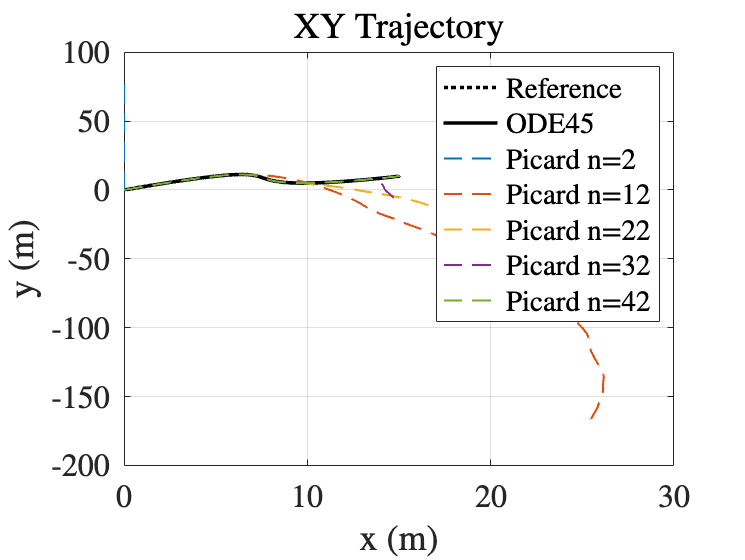


% --- Picard Iterations (Closed-Loop) ---
max_iter_cl = 50;
x_pic_cl = cell(1, max_iter_cl);
x0_cl = xref_cl(:,1);
x_p_cl = repmat(x0_cl, 1, N_cl);   % initial guess

plot_iters_cl = 2:10:max_iter_cl;          % only even iterations
colors_cl = lines(numel(plot_iters_cl));
iter_labels_cl = arrayfun(@(k) sprintf('Picard n=%d', k), plot_iters_cl, 'UniformOutput', false);

for k = 1:max_iter_cl
    f_val_cl = zeros(6, N_cl);
    for i = 1:N_cl
        xe_i = x_p_cl(:,i) - xref_cl(:,i);
        u_i  = uref_cl(:,i) - K_cl(:,:,i) * xe_i;
        th_i = x_p_cl(5,i);
        f_val_cl(:,i) = [
            x_p_cl(2,i);
            -(u_i(1)+u_i(2))*sin(th_i)/m;
            x_p_cl(4,i);
            (u_i(1)+u_i(2))*cos(th_i)/m - g;
            x_p_cl(6,i);
            r*(u_i(1)-u_i(2))/I
        ];
    end
    x_p_cl = x0_cl + cumtrapz(t_cl, f_val_cl, 2);
    x_pic_cl{k} = x_p_cl;
end

% --- ODE45 Reference (Closed-Loop) ---
[t_ode_cl, x_ode_cl] = ode45( ...
    @(t, x) cl_dyn(t, x, t_cl, xref_cl, uref_cl, K_cl, m, I, r, g, dt_cl, N_cl), ...
    [0 T_cl], x0_cl);
x_ode_cl = x_ode_cl';
t_ode_cl = t_ode_cl';

% --- Figure 5: XY Trajectory vs Reference ---
figure
plot(xref_cl(1,:), xref_cl(3,:), 'k:', 'LineWidth', 2, 'DisplayName', 'Reference')
hold on
plot(x_ode_cl(1,:), x_ode_cl(3,:), 'k-', 'LineWidth', 2, 'DisplayName', 'ODE45')
for ki = 1:numel(plot_iters_cl)
    k = plot_iters_cl(ki);
    plot(x_pic_cl{k}(1,:), x_pic_cl{k}(3,:), '--', ...
        'Color', colors_cl(ki,:), 'LineWidth', 1.2, 'DisplayName', iter_labels_cl{ki})
end
xlabel('x (m)'); ylabel('y (m)')
title('XY Trajectory')
legend; grid on

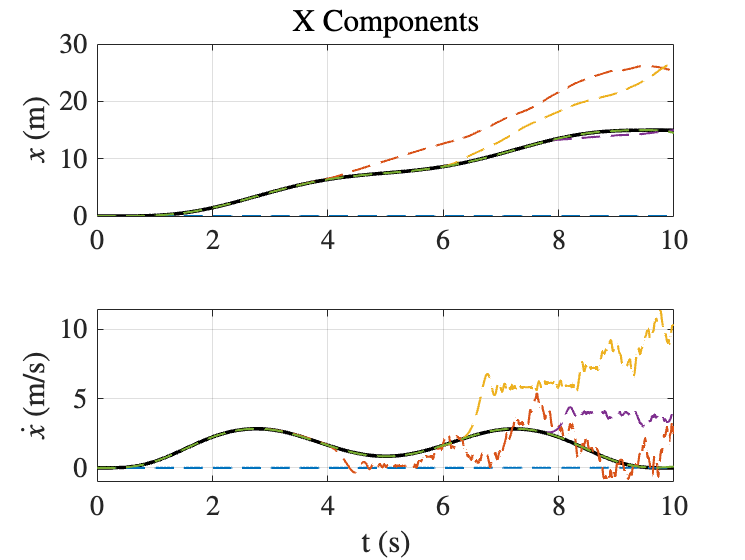


% --- Figure 6: x and x-dot ---
figure
subplot(2,1,1)
plot(t_ode_cl, x_ode_cl(1,:), 'k-', 'LineWidth', 2, 'DisplayName', 'ODE45'); hold on
for ki = 1:numel(plot_iters_cl)
    k = plot_iters_cl(ki);
    plot(t_cl, x_pic_cl{k}(1,:), '--', 'Color', colors_cl(ki,:), 'LineWidth', 1.2, 'DisplayName', iter_labels_cl{ki})
end
ylabel('$x$ (m)', 'Interpreter', 'latex'); grid on
title('X Components')

subplot(2,1,2)
plot(t_ode_cl, x_ode_cl(2,:), 'k-', 'LineWidth', 2, 'DisplayName', 'ODE45'); hold on
for ki = 1:numel(plot_iters_cl)
    k = plot_iters_cl(ki);
    plot(t_cl, x_pic_cl{k}(2,:), '--', 'Color', colors_cl(ki,:), 'LineWidth', 1.2, 'DisplayName', iter_labels_cl{ki})
end
xlabel('t (s)'); ylabel('$\dot{x}$ (m/s)', 'Interpreter', 'latex'); grid on

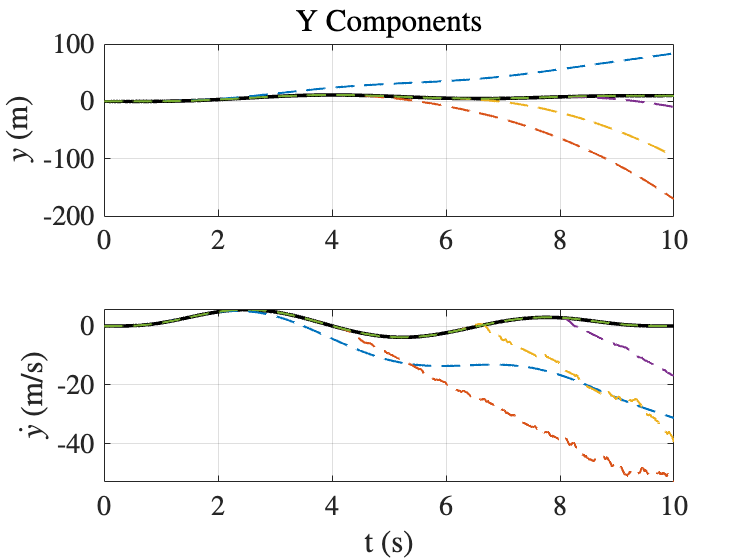


% --- Figure 7: y and y-dot ---
figure
subplot(2,1,1)
plot(t_ode_cl, x_ode_cl(3,:), 'k-', 'LineWidth', 2, 'DisplayName', 'ODE45'); hold on
for ki = 1:numel(plot_iters_cl)
    k = plot_iters_cl(ki);
    plot(t_cl, x_pic_cl{k}(3,:), '--', 'Color', colors_cl(ki,:), 'LineWidth', 1.2, 'DisplayName', iter_labels_cl{ki})
end
ylabel('$y$ (m)', 'Interpreter', 'latex'); grid on
title('Y Components')

subplot(2,1,2)
plot(t_ode_cl, x_ode_cl(4,:), 'k-', 'LineWidth', 2, 'DisplayName', 'ODE45'); hold on
for ki = 1:numel(plot_iters_cl)
    k = plot_iters_cl(ki);
    plot(t_cl, x_pic_cl{k}(4,:), '--', 'Color', colors_cl(ki,:), 'LineWidth', 1.2, 'DisplayName', iter_labels_cl{ki})
end
xlabel('t (s)'); ylabel('$\dot{y}$ (m/s)', 'Interpreter', 'latex'); grid on

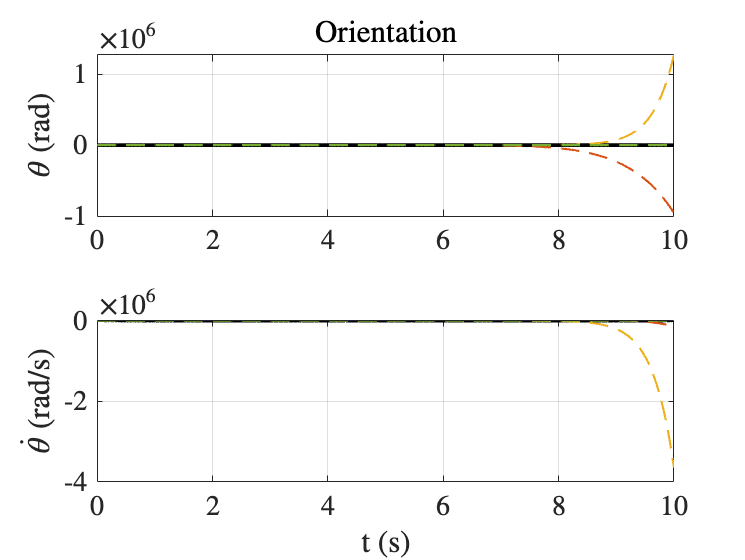


% --- Figure 8: theta and theta-dot ---
figure
subplot(2,1,1)
plot(t_ode_cl, x_ode_cl(5,:), 'k-', 'LineWidth', 2, 'DisplayName', 'ODE45'); hold on
for ki = 1:numel(plot_iters_cl)
    k = plot_iters_cl(ki);
    plot(t_cl, x_pic_cl{k}(5,:), '--', 'Color', colors_cl(ki,:), 'LineWidth', 1.2, 'DisplayName', iter_labels_cl{ki})
end
ylabel('$\theta$ (rad)', 'Interpreter', 'latex'); grid on
title('Orientation')

subplot(2,1,2)
plot(t_ode_cl, x_ode_cl(6,:), 'k-', 'LineWidth', 2, 'DisplayName', 'ODE45'); hold on
for ki = 1:numel(plot_iters_cl)
    k = plot_iters_cl(ki);
    plot(t_cl, x_pic_cl{k}(6,:), '--', 'Color', colors_cl(ki,:), 'LineWidth', 1.2, 'DisplayName', iter_labels_cl{ki})
end
xlabel('t (s)'); ylabel('$\dot{\theta}$ (rad/s)', 'Interpreter', 'latex'); grid on


function xdot = cl_dyn(t, x, t_cl, xref_cl, uref_cl, K_cl, m, I, r, g, dt_cl, N_cl)
    % Closed-loop dynamics for ODE45: evaluates f(x, u(t)) where
    % u(t) = u_ref(t) - K(t)*(x - x_ref(t)), with precomputed K and references.
    i = min(max(round(t/dt_cl) + 1, 1), N_cl);
    xe = x - xref_cl(:,i);
    u  = uref_cl(:,i) - K_cl(:,:,i) * xe;
    xdot = [x(2);
            -(u(1)+u(2))*sin(x(5))/m;
            x(4);
            (u(1)+u(2))*cos(x(5))/m - g;
            x(6);
            r*(u(1)-u(2))/I];
end
